Call the ROC script

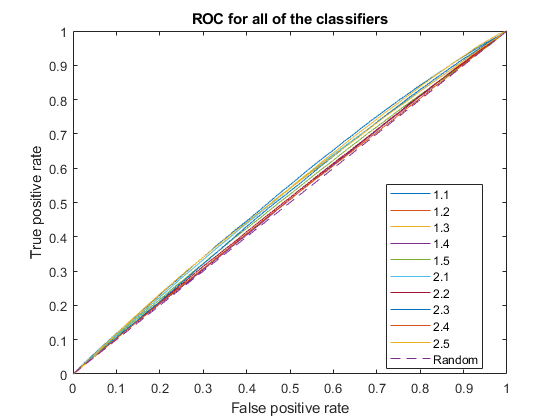

AUC11 = 0.5364

AUC12 = 0.5081

AUC13 = 0.5317

AUC14 = 0.5065

AUC15 = 0.5162

AUC21 = 0.5263

AUC22 = 0.5105

AUC23 = 0.5221

AUC24 = 0.5057

AUC25 = 0.5280

roc_v9_first_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9692

ans = 134

ans = 0.7526

ans = 0.2372

ans = 0.7526

ans = 0.6863

ans = 0.7385

Classifier 2

ans = 0.9692

ans = 165

ans = 0.5801

ans = 0.4708

ans = 0.5801

ans = 0.8805

ans = 0.8914

Classifier 3

ans = 0.9871

ans = 155

ans = 0.7259

ans = 0.2712

ans = 0.7259

ans = 0.8077

ans = 0.8459

Classifier 4

ans = 0.9696

ans = 186

ans = 0.5756

ans = 0.4219

ans = 0.5756

ans = 0.9951

ans = 0.9970

Classifier 5

ans = 0.9820

ans = 71

ans = 0.6198

ans = 0.3949

ans = 0.6198

ans = 0.3664

ans = 0.3915

Classifier 6

ans = 0.0244

ans = 109

ans = 0.6893

ans = 0.3322

ans = 0.6893

ans = 0.5619

ans = 0.6031

Classifier 7

ans = 8.8606e-04

ans = 147

ans = 0.5741

ans = 0.4266

ans = 0.5741

ans = 0.7798

ans = 0.7927

Classifier 8

ans = 3.5738e-04

ans = 139

ans = 0.6789

ans = 0.3359

ans = 0.6789

ans = 0.7258

ans = 0.7601

Classifier 9

ans = 8.6907e-04

ans = 95

ans = 0.5489

ans = 0.4542

ans = 0.5489

ans = 0.5024

ans = 0.5128

Classifier 10

ans = 1.3037e-06

ans = 74

ans = 0.6994

ans = 0.3206

ans = 0.6994

ans = 0.3728

ans = 0.4163

Save results

save('./results_characterization/v9_first_op.mat','selectedPoints');